clc
close all

# Partie 1

# Partie 2

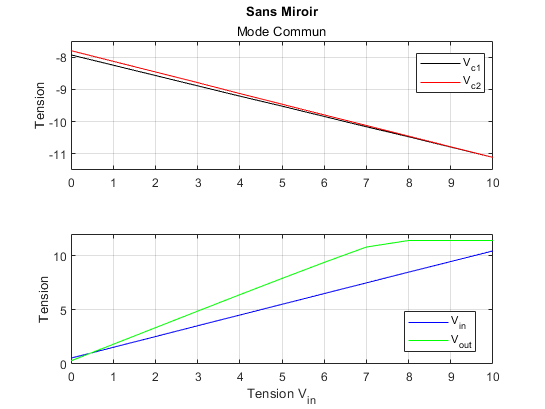

Vin=0:1:10;
%------ Montage sans miroir de courant
% Mode Commun
Vc1=[-7.93 -8.25 -8.57 -8.89 -9.21 -9.52 -9.84 -10.16 -10.47 -10.79 -11.11];
Vc2=[-7.80 -8.13 -8.46 -8.79 -9.13 -9.46 -9.79 -10.12 -10.45 -10.78 -11.11];
Vout=[296e-3 1.821 3.35 4.88 6.40 7.90 9.38 10.80 11.40 11.40 11.40 ];
Ve=[544e-3 1.538 2.53 3.53 4.52 5.51 6.50 7.49 8.48 9.46 10.44];

figure
subplot(2,1,1)
plot(Vin,Vc1,'k',Vin,Vc2,'r')
legend('V_c_1','V_c_2','location','best')
ylabel('Tension')
title('Sans Miroir','Mode Commun')
ylim([-11.5 -7.5])
grid on

subplot(2,1,2)
plot(Vin,Ve,'b',Vin,Vout,'g')
legend('V_i_n','V_o_u_t','location','best')
xlabel('Tension V_i_n')
ylabel('Tension')
ylim([0 12])
grid on

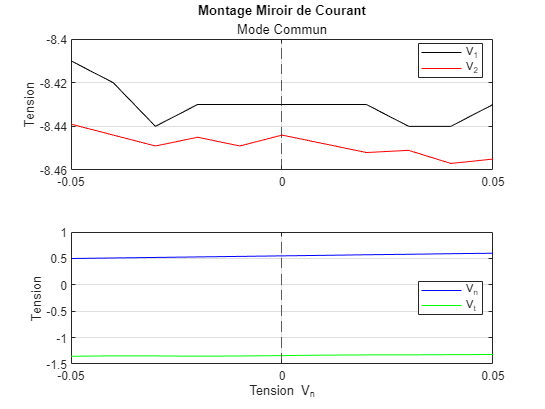

%------ Montage avec le miroir de courant
% Mode Commun
Vin = -50e-3:10e-3:50e-3;
Vc1 = [8.41  8.42  8.44  8.43  8.43  8.43  8.43  8.43  8.44  8.44  8.43];Vc1=-1.*Vc1;
Vc2 = [8.439 8.444 8.449 8.445 8.449 8.444 8.448 8.452 8.451 8.457 8.455];Vc2=-1.*Vc2;
Ve =  [.498   .508   .518   .528   .538   .548   .558   .569   .578   .589   .598];
Vout =[-1.354 -1.345 -1.347 -1.352 -1.348 -1.341 -1.332 -1.328 -1.327 -1.323 -1.32];

figure
subplot(2,1,1)
plot(Vin,Vc1,'k',Vin,Vc2,'r')
xline(0,'--');
legend('V_c_1','V_c_2','location','best')
ylabel('Tension')
title('Montage Miroir de Courant','Mode Commun')
grid on

subplot(2,1,2)
plot(Vin,Ve,'b',Vin,Vout,'g')
xline(0,'--');
legend('V_i_n','V_o_u_t','location','best')
xlabel('Tension V_i_n')
ylabel('Tension')
ylim([-1.5 1])
grid on

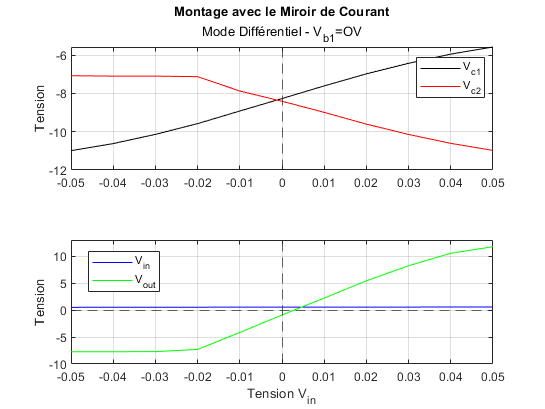


% Mode Différentiel
%%% VB1 a la masse
Vin = -50e-3:10e-3:50e-3;
Vc1 = [10.99 10.62 10.14 9.58  8.92  8.27  7.61  6.98  6.43   5.95   5.58];Vc1=-1.*Vc1;
Vc2 = [7.08  7.1   7.1   7.127 7.877 8.412 8.991 9.605 10.145 10.610 10.978];Vc2=-1.*Vc2;
Ve =  [.513 .521   .529 0.536  .542  0.548 .554 .557 .560 .563  .565];
Vout =[-7.72 -7.72 -7.71  -7.3 -4.15 -.91  2.22 5.43 8.23 10.54 11.76];

figure
subplot(2,1,1)
plot(Vin,Vc1,'k',Vin,Vc2,'r')
xline(0,'--');
legend('V_c_1','V_c_2','location','best')
ylabel('Tension')
title('Montage avec le Miroir de Courant','Mode Différentiel - V_b_1=OV')
grid on

subplot(2,1,2)
plot(Vin,Ve,'b',Vin,Vout,'g')
yline(0,'--');
xline(0,'--');
legend('V_i_n','V_o_u_t','location','best')
xlabel('Tension V_i_n')
ylabel('Tension')
ylim([-10 13])
grid on